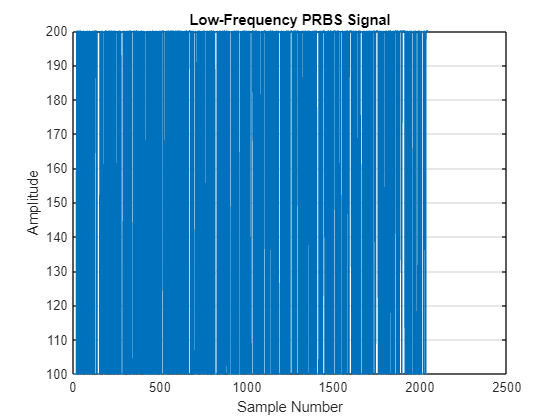

% Parameters
N = 2046; % Number of samples
fs = 100; % Sampling frequency (Hz)

% Generate low-frequency PRBS signal
uk = idinput(N, 'prbs', [0 1/2], [-50 50]) + 150;

% Plot the signal
figure;
plot(uk);
title('Low-Frequency PRBS Signal');
xlabel('Sample Number');
ylabel('Amplitude');
grid on;

% Prepare the C array format
cArrayFormat = sprintf('double uk[%d] = {', N);
cArrayFormat = [cArrayFormat, sprintf('%d, ', uk(1:end-1)), sprintf('%d};', uk(end))];
% Save the C array format to a text file
filename = 'prbs_signal_array_range_2.txt';
fileID = fopen(filename, 'w');
fprintf(fileID, '%s\n', cArrayFormat);
fclose(fileID);

disp(['C array saved to ', filename]);

C array saved to prbs_signal_array_range_2.txt


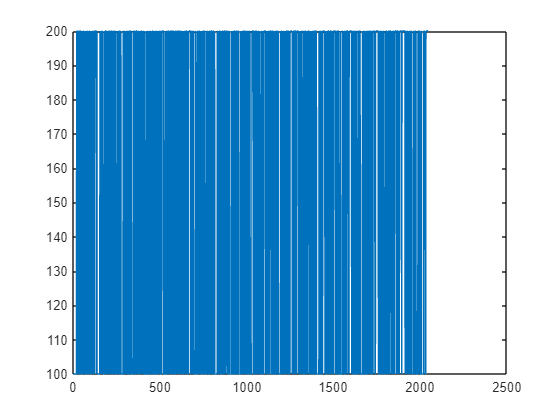

% Read data from the CSV file
%data = readtable('recovered_data_range_2.csv');
data = readtable('step_response_data.csv');
% Extract data from the table into arrays
output = data.Output; % Assuming 'Var1' is your first variable
input = data.Time; % Assuming 'Var2' is your second variable

%output = detrend(output_bef);
%input = detrend(input_bef);


plot(input);

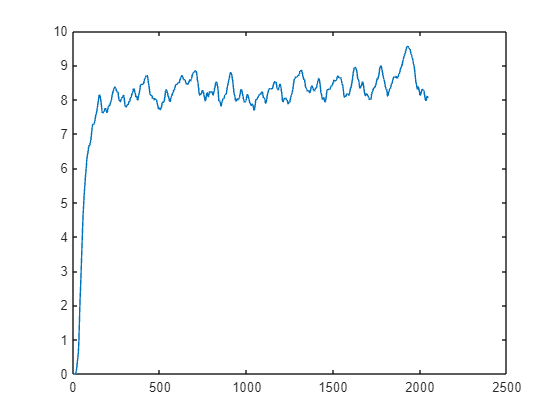

plot(output);  

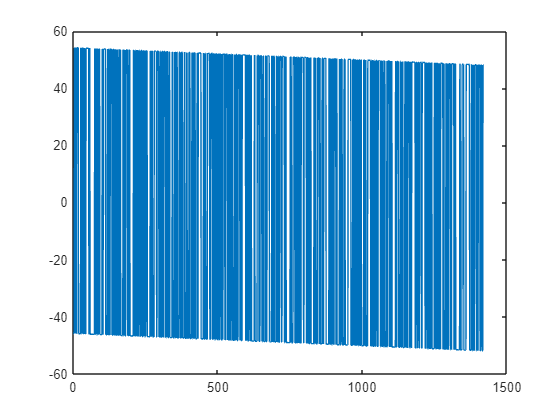

out1 = output(81:1500);    %starting with 81 to remove rise time             
out2 = output(1501:end);
inp1 = input(81:1500);     %starting with 81 to remove rise time                
inp2 = input(1501:end);                 

% 1 is the sample time
data_train = detrend(iddata( out1, inp1, 0.01)); 
data_test = detrend(iddata( out2, inp2, 0.01));

%plot the input 
detrend_input = detrend(inp1);
plot(detrend_input);

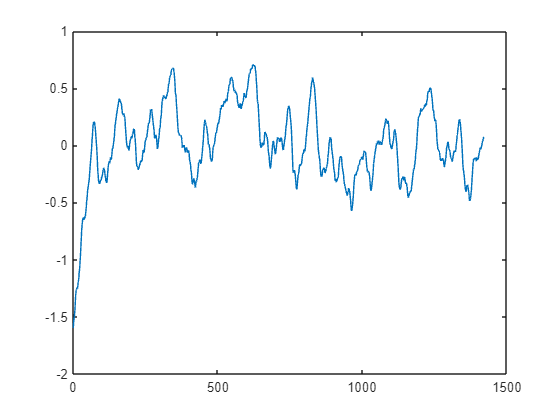

detrend_out = detrend(out1);
plot(detrend_out);

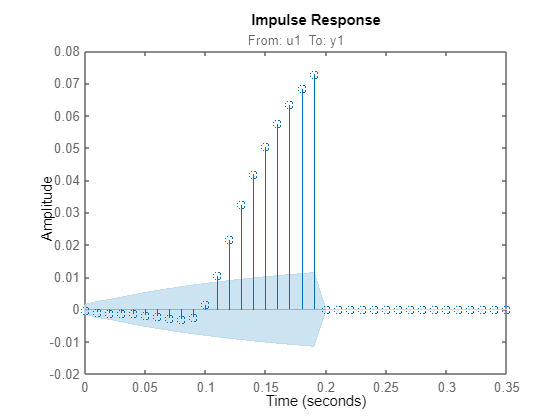

% IR estimation
fir_mod = impulseest( data_train, 20);
figure; 
impulseplot(fir_mod,'sd', 3)

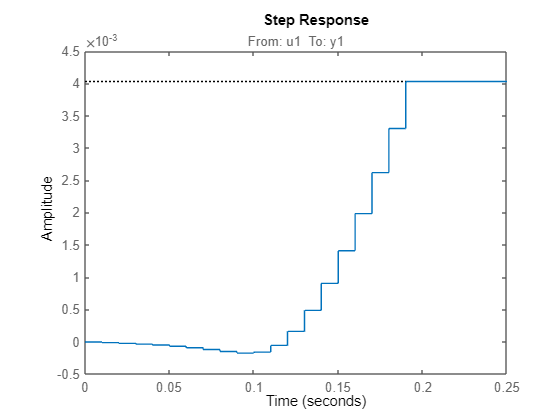

% Step response estimation
figure; step(fir_mod);

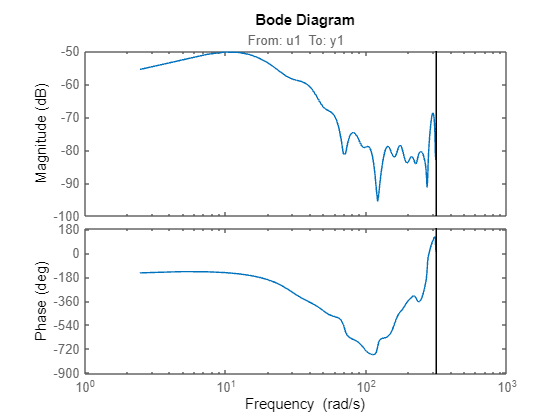

% FRF estimation
[Gwhat ,wvec] = spa(data_train);
figure; bode(Gwhat);

% FRF estimation
n4sid( data_train, 1:10);
% Set the range for orders
nn_mod = struc( 1:4, 1:4, 3);
% Compute ARX models and the associated loss functions
V = arxstruc( data_train, data_test , nn_mod);
% Select the best model
best_ord = selstruc(V, 8);

% Estimate the best ARX structure
modarx_best = arx(data_train , [ 2 2 4]);
present(modarx_best)

                                                                                                                                                                                                                                                                                                                                      
modarx_best =                                                                                                                                                                                                                                                                                                                         
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                                                                                                                                                                                                   
  A(z) = 1 - 1.8 (+

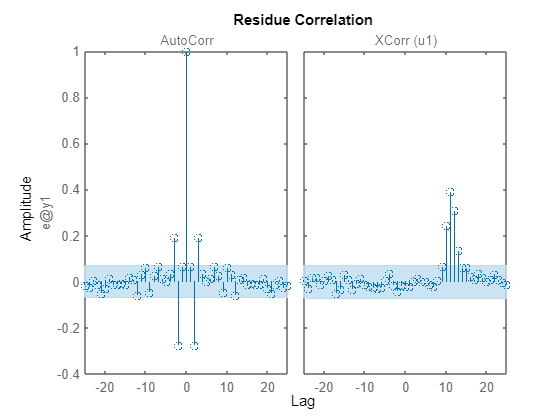

% Residual analysis
figure; 
resid( modarx_best, data_train);

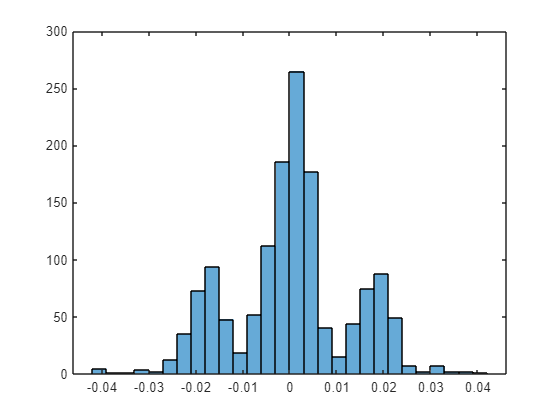

% Compute prediction errors
err_modarx = pe(modarx_best ,data_train ,1);
% Histogram
figure; histogram(err_modarx.y);

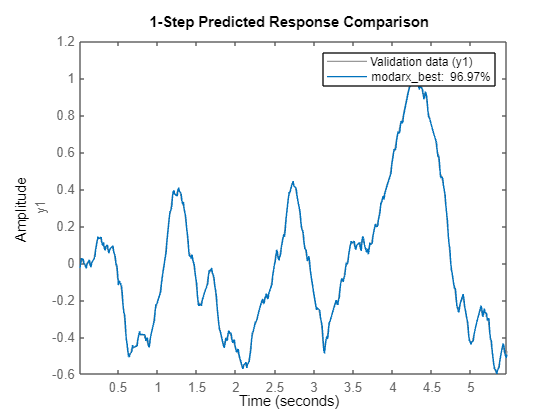

% Compute the predictions and return the fits
compare( data_test, modarx_best, 1);

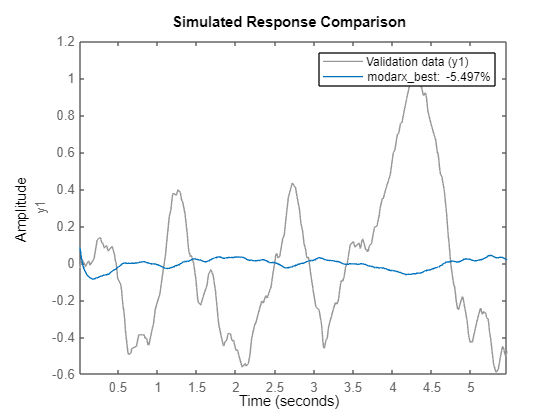

compare( data_test, modarx_best, inf);

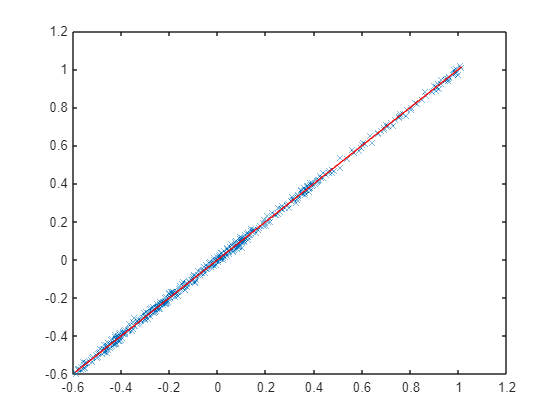

% Compute the predictions and return the fits
[yhat_1step ,fit1] = compare( data_test ,modarx_best ,1);
[yhat_infstep ,fit_inf] = compare( data_test ,modarx_best ,inf);

figure; 
plot(data_test.y, yhat_1step.y,'x');
hold on
plot(data_test.y, data_test.y,'r-');
hold off;

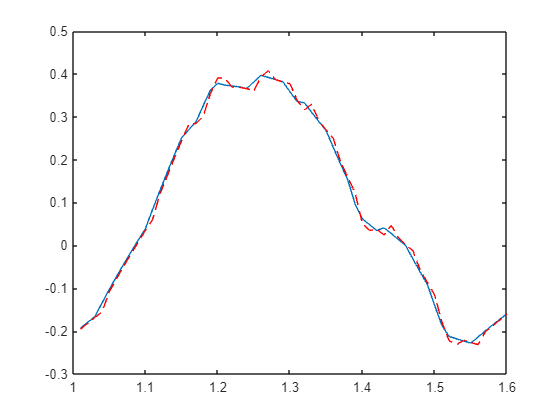

Tvec = 101:160;
figure; 
plot(data_test.SamplingInstants(Tvec),data_test.y(Tvec)); hold on
plot(data_test.SamplingInstants(Tvec),yhat_1step.y(Tvec),'r--');
hold off;

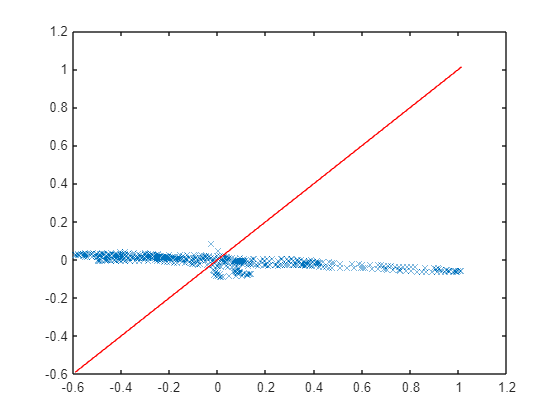

figure
plot(data_test.y,yhat_infstep.y,'x'); hold on
plot(data_test.y,data_test.y,'r-');
hold off;

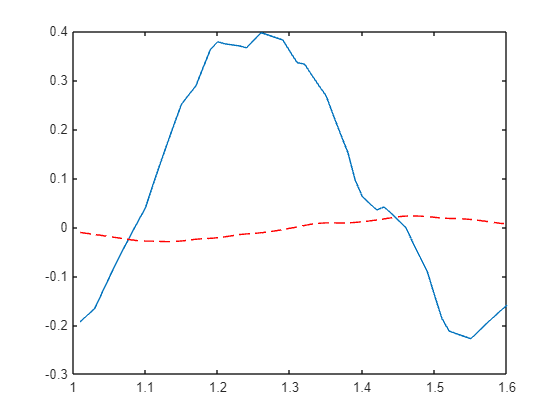

figure;
plot(data_test.SamplingInstants(Tvec),data_test.y(Tvec)); hold on
plot(data_test.SamplingInstants(Tvec),yhat_infstep.y(Tvec),'r--')
hold off;

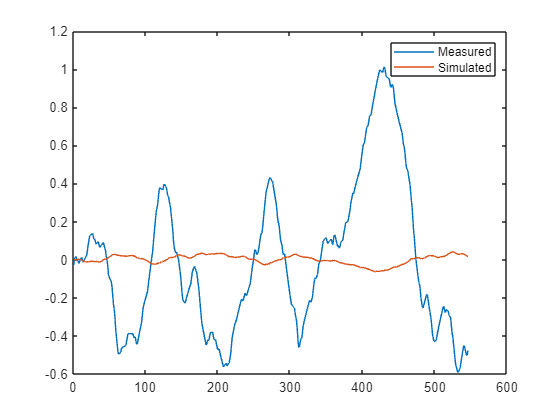

% Simulate model on test data
y_sim = sim( modarx_best, data_test.InputData);
plot(data_test.OutputData);
hold on
plot(y_sim)
hold off
legend('Measured', 'Simulated');

d2c(modarx_best)

ans =
Continuous-time ARMAX model: A(s)y(t) = B(s)u(t) + C(s)e(t)
  A(s) = s^2 + 21.71 s + 51.96                             
                                                           
  B(s) = 0.0004758 s - 0.1338                              
                                                           
  C(s) = s^2 + 164.7 s + 1.113e04                          
                                                           
Input delays (listed by channel): 0.03                     
Parameterization:
   Polynomial orders:   na=2   nb=2   nc=2   nk=0
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 


% Choose ARMAX model orders
na = 2;  % A(q) order
nb = 1;  % B(q) order
nc = 2;  % C(q) order
nk = delayest(data_train)  % Input-output delay

nk = 11


% Estimate ARMAX model
model_armax = armax(data_train, [na nb nc nk])

model_armax =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 1.88 z^-1 + 0.8828 z^-2                     
                                                         
  B(z) = 0.0001262 z^-11                                 
                                                         
  C(z) = 1 + 0.1101 z^-1 - 0.8744 z^-2                   
                                                         
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=1   nc=2   nk=11
   Number of free coefficients: 5
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using ARMAX on time domain data "data_train".
Fit to estimation data: 97.51% (prediction focus)      
FPE: 8.456e-05, MSE: 8.373e-05                         
 


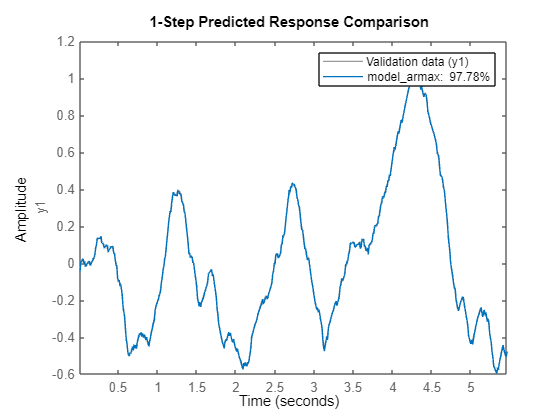

% Validate the model
compare(data_test, model_armax, 1);

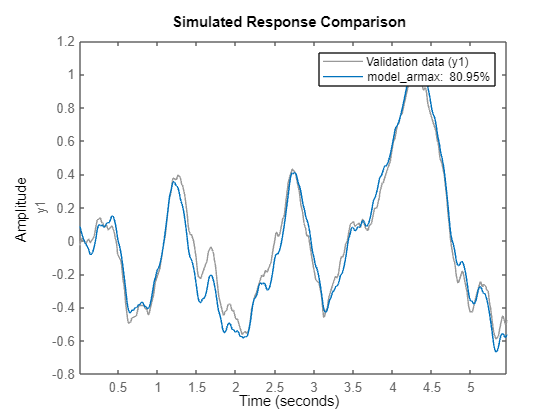

% Validate the model
compare(data_test, model_armax, inf);

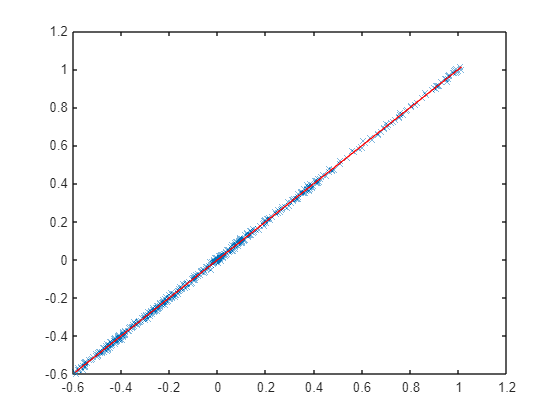

% Compute the predictions and return the fits
[yhat_1step ,fit1] = compare( data_test ,model_armax ,1);
[yhat_infstep ,fit_inf] = compare( data_test ,model_armax ,inf);

figure; 
plot(data_test.y, yhat_1step.y,'x');
hold on
plot(data_test.y, data_test.y,'r-');
hold off;

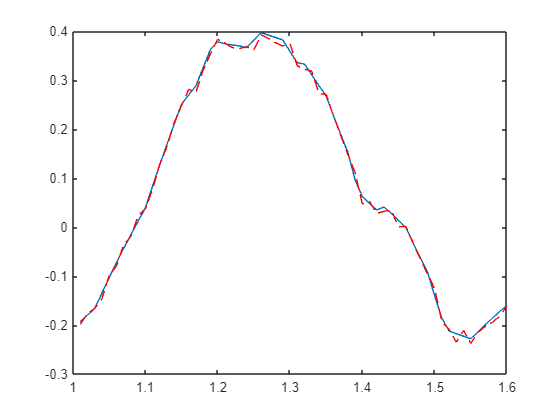

Tvec = 101:160;
figure; 
plot(data_test.SamplingInstants(Tvec),data_test.y(Tvec)); hold on
plot(data_test.SamplingInstants(Tvec),yhat_1step.y(Tvec),'r--');
hold off;

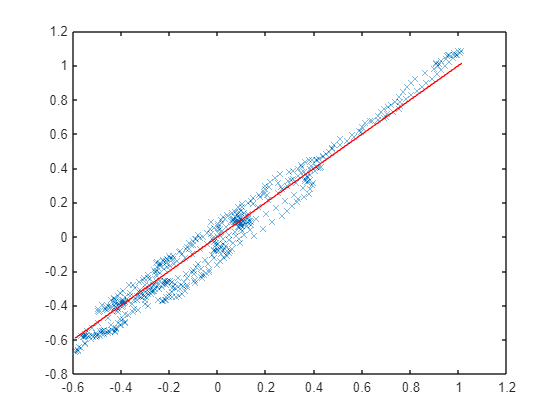

figure
plot(data_test.y,yhat_infstep.y,'x'); hold on
plot(data_test.y,data_test.y,'r-');
hold off;

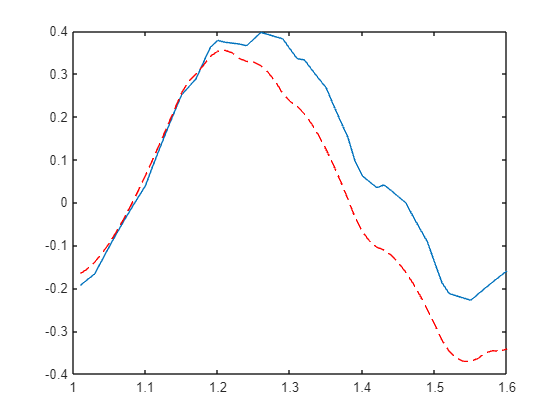

figure;
plot(data_test.SamplingInstants(Tvec),data_test.y(Tvec)); hold on
plot(data_test.SamplingInstants(Tvec),yhat_infstep.y(Tvec),'r--')
hold off;

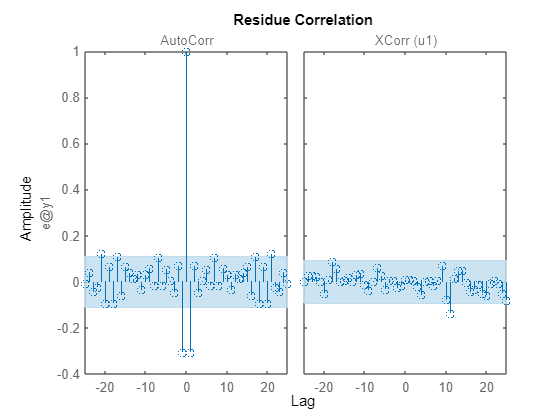

% Residual analysis
resid(model_armax, data_test);

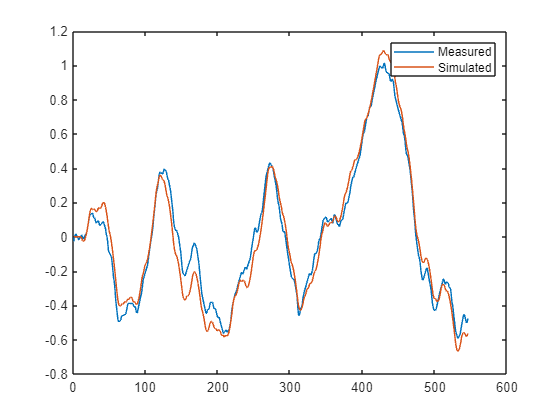

% Simulate model on test data
y_sim_armax = sim(model_armax, data_test.InputData);
plot(data_test.OutputData);
hold on
plot(y_sim_armax)
hold off
legend('Measured', 'Simulated');

d2c(model_armax)

ans =
Continuous-time ARMAX model: A(s)y(t) = B(s)u(t) + C(s)e(t)
  A(s) = s^2 + 12.47 s + 29.86                             
                                                           
  B(s) = 0.006573 s + 1.342                                
                                                           
  C(s) = s^2 + 211.6 s + 2508                              
                                                           
Input delays (listed by channel): 0.1                      
Parameterization:
   Polynomial orders:   na=2   nb=2   nc=2   nk=0
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 


nb = 2;  % B(q) order
nf = 2;  % F(q) order
nc = 2;  % C(q) order
nd = 2;  % D(q) order
nk = delayest(data_train)  % Input-output delay

nk = 11

model_bj = bj(data_train, [nb nf nc nd nk])% Validate the model

model_bj =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = 0.0001026 z^-11 + 3.355e-05 z^-12                      
                                                                
  C(z) = 1 + 0.9769 z^-1 - 0.02143 z^-2                         
                                                                
  D(z) = 1 - 0.7913 z^-1 - 0.1978 z^-2                          
                                                                
  F(z) = 1 - 1.873 z^-1 + 0.877 z^-2                            
                                                                
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nc=2   nd=2   nf=2   nk=11
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using BJ on time domain data "data_train".
Fit to estimation data: 97.61% (prediction focus)   
FPE: 7.856e-05, MSE: 7.724

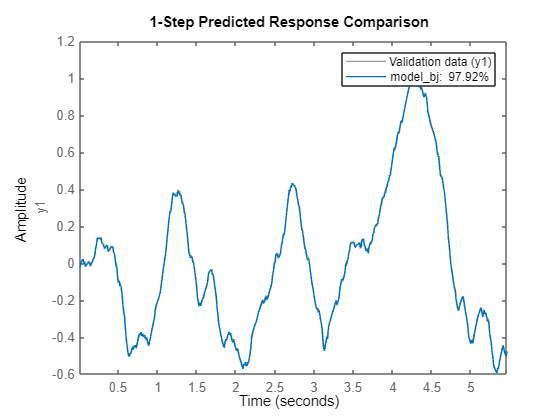

compare(data_test, model_bj, 1);

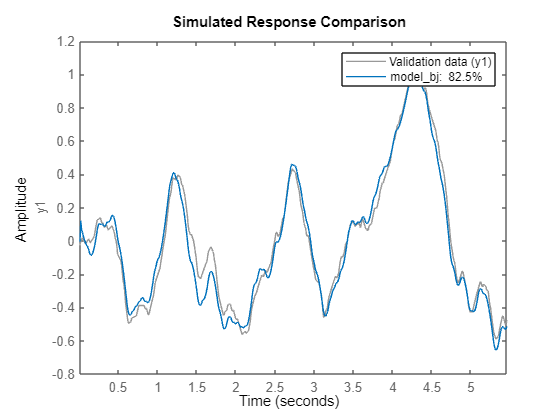

% Validate the model
compare(data_test, model_bj, inf);

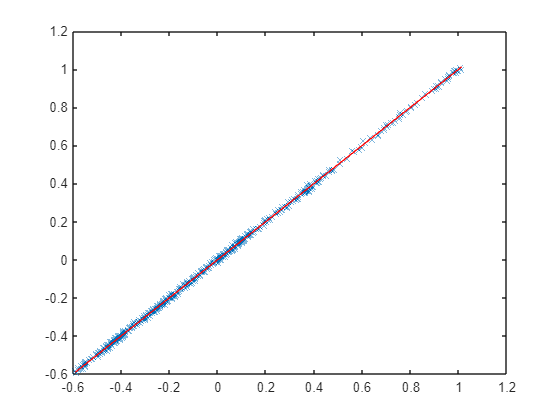

% Compute the predictions and return the fits
[yhat_1step ,fit1] = compare( data_test ,model_bj ,1);
[yhat_infstep ,fit_inf] = compare( data_test ,model_bj ,inf);

figure; 
plot(data_test.y, yhat_1step.y,'x');
hold on
plot(data_test.y, data_test.y,'r-');
hold off;

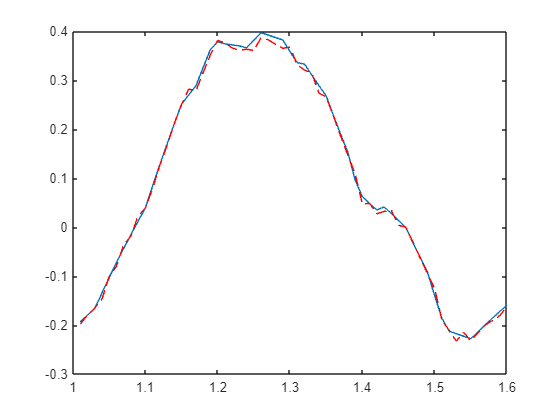

Tvec = 101:160;
figure; 
plot(data_test.SamplingInstants(Tvec),data_test.y(Tvec)); hold on
plot(data_test.SamplingInstants(Tvec),yhat_1step.y(Tvec),'r--');
hold off;

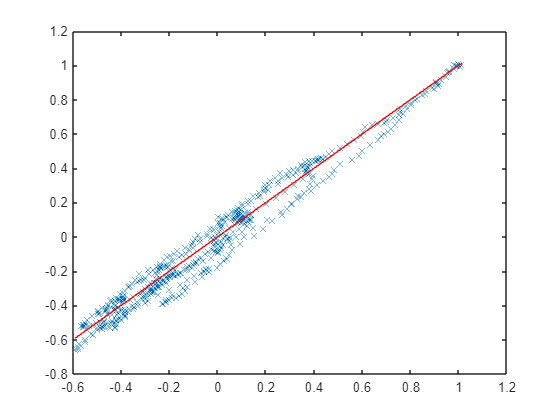

figure
plot(data_test.y,yhat_infstep.y,'x'); hold on
plot(data_test.y,data_test.y,'r-');
hold off;

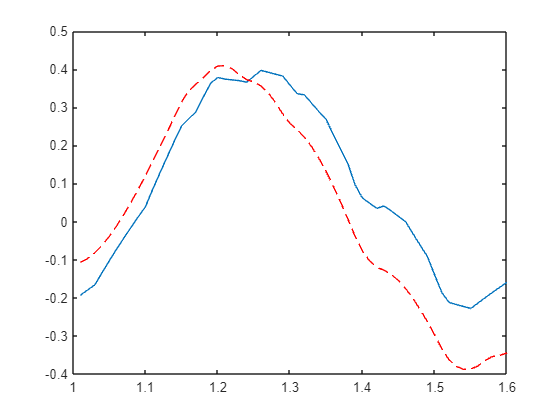

figure;
plot(data_test.SamplingInstants(Tvec),data_test.y(Tvec)); hold on
plot(data_test.SamplingInstants(Tvec),yhat_infstep.y(Tvec),'r--')
hold off;

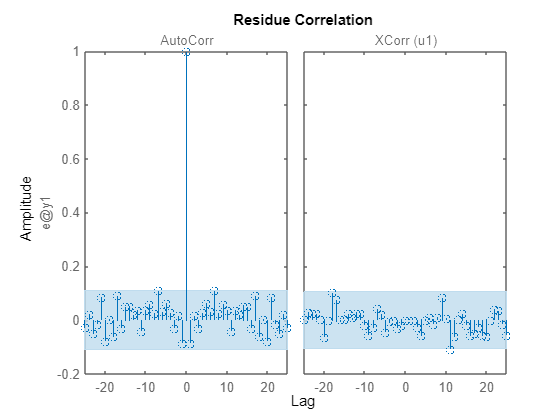

resid(model_bj, data_test);     % Residual analysis

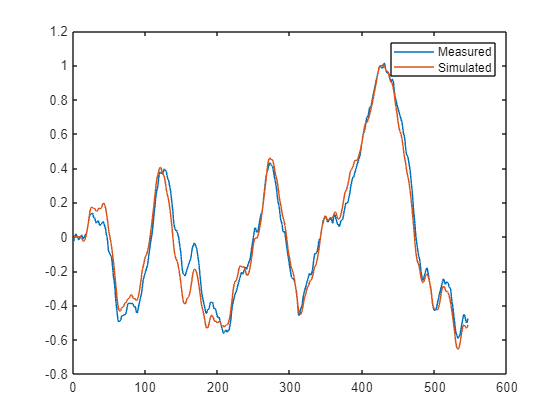

% Simulate model on test data
y_sim_box_jenkins = sim( model_bj, data_test.InputData);
plot(data_test.OutputData);
hold on
plot(y_sim_box_jenkins)
hold off
legend('Measured', 'Simulated');

d2c(model_bj)

ans =
Continuous-time BJ model: y(t) = [B(s)/F(s)]u(t) + [C(s)/D(s)]e(t)
  B(s) = 0.003529 s + 1.454                                       
                                                                  
  C(s) = s^3 + 505.8 s^2 + 1.928e05 s + 2.041e07                  
                                                                  
  D(s) = s^3 + 323.2 s^2 + 1.25e05 s + 1.143e05                   
                                                                  
  F(s) = s^2 + 13.13 s + 38.62                                    
                                                                  
Input delays (listed by channel): 0.1                             
Parameterization:
   Polynomial orders:   nb=2   nc=3   nd=3   nf=2   nk=0
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
<a

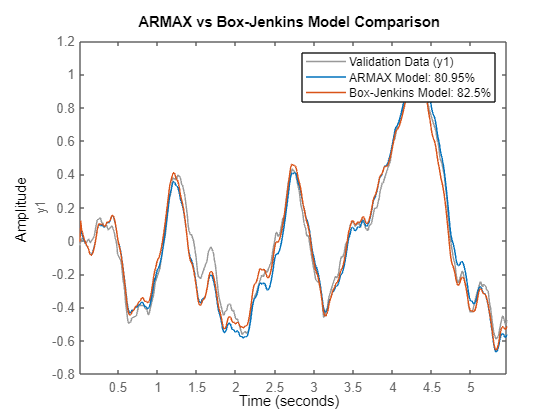

% Plot comparison for validation data
figure;
compare(data_test, model_armax, model_bj);

% Add legends and titles for clarity
legend('Validation Data', 'ARMAX Model', 'Box-Jenkins Model');
title('ARMAX vs Box-Jenkins Model Comparison');

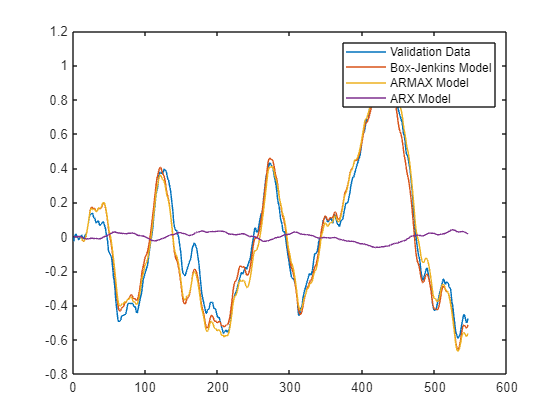

xlabel('Time');
ylabel('Amplitude');

plot(data_test.OutputData);
hold on
plot(y_sim_box_jenkins)
plot(y_sim_armax)
plot(y_sim)
hold off
% Add legends and titles for clarity
legend('Validation Data', 'Box-Jenkins Model', 'ARMAX Model', 'ARX Model');

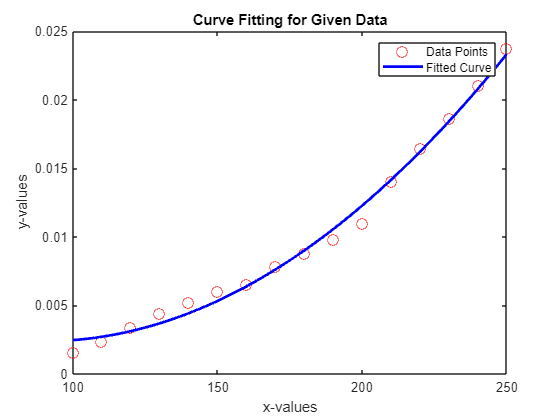

%ARMAX Model 2
% Data from the image
x = [100, 110, 120, 130, 140, 150, 160, 170, 180, 190, 200, 210, 220, 230, 240, 250];
y = [0.0016, 0.0024, 0.0034, 0.0044, 0.0052, 0.006, 0.0065, 0.0078, 0.0088, 0.0098, 0.011, 0.014, 0.0164, 0.0186, 0.021, 0.0237];

% Fit a polynomial curve (degree 2, but you can change it to degree 1, 3, etc.)
p = polyfit(x, y, 2);

% Generate points to plot the fitted curve
x_fit = linspace(min(x), max(x), 100);
y_fit = polyval(p, x_fit);

% Plot the data points
figure;
plot(x, y, 'ro', 'MarkerSize', 8, 'DisplayName', 'Data Points'); 
hold on;

% Plot the fitted curve
plot(x_fit, y_fit, 'b-', 'LineWidth', 2, 'DisplayName', 'Fitted Curve');

% Add labels and legend
xlabel('x-values');
ylabel('y-values');
title('Curve Fitting for Given Data');
legend show;


% Display polynomial coefficients
disp('Polynomial coefficients:');

Polynomial coefficients:


disp(p);

    0.0000   -0.0001    0.0090



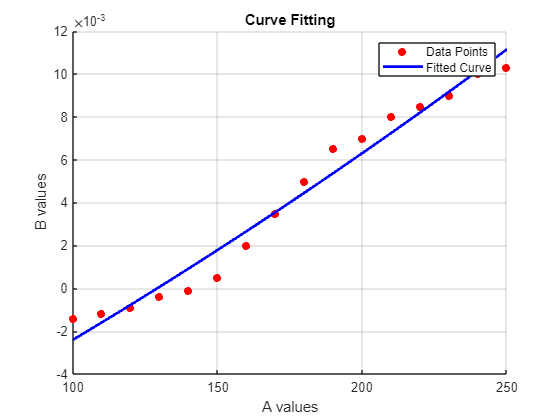

%BJ Models
% Input data
x = [100, 110, 120, 130, 140, 150, 160, 170, 180, 190, 200, 210, 220, 230, 240, 250]; % A values
y = [-0.0014, -0.0012, -0.0009, -0.0004, -0.0001, 0.0005, 0.0020, 0.0035, 0.0050, 0.0065, 0.0070, 0.0080, 0.0085, 0.0090, 0.0100, 0.0103]; % B values

% Curve fitting
% Choose a polynomial degree, e.g., 2 for quadratic
degree = 2;
[p, S] = polyfit(x, y, degree);

% Generate points for the fitted curve
x_fit = linspace(min(x), max(x), 100); % 100 points between min and max of x
y_fit = polyval(p, x_fit);

% Plotting
figure;
scatter(x, y, 'filled', 'r'); % Original data points
hold on;
plot(x_fit, y_fit, 'b-', 'LineWidth', 2); % Fitted curve
xlabel('A values');
ylabel('B values');
title('Curve Fitting');
legend('Data Points', 'Fitted Curve');
grid on;
hold off;


% Display the model
model_string = sprintf('y = %.4fx^2 + %.4fx + %.4f', p(1), p(2), p(3));
disp('Fitted Model:');

Fitted Model:


disp(model_string);

y = 0.0000x^2 + 0.0001x + -0.0098
